initial_beam_position = 16;

% fai una simulazione con real_bias uguale a zero e poi vedi cosa viene fuori.

real_bias = 3.2374; 

data = sim("bias_estimation_box.slx");

### Searching for referenced models in model 'bias_estimation_box'.
### Found 0 model reference targets to update.



t1 = data.ScopeData1.time;
tetha_h1 = data.ScopeData1.signals(1).values;  
tetha_d1 = data.ScopeData1.signals(2).values;
ref_signal1 = data.ScopeData1.signals(3).values;
command_u1 =  data.ScopeData1.signals(4).values;
bias_measured = tetha_d1(end);
disp(bias_measured);

  -4.5914e-05



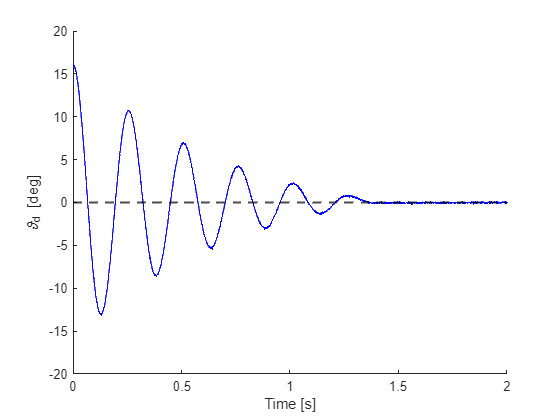

save("estimation_box",'t1','tetha_h1','tetha_d1','ref_signal1','command_u1');

load("estimation_box.mat");

figure;
hold on 
plot(t1,tetha_d1,'b');
yline(0, 'k--', 'LineWidth', 1.5);
axis([0 2 -20 20])
xlabel('Time [s]');
ylabel('\vartheta_d [deg]');
hold off

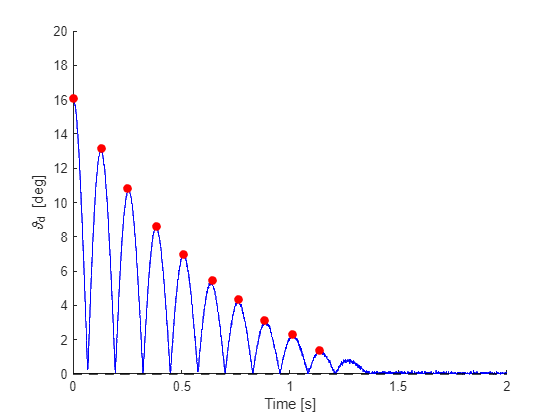



% Trova tutti picchi. Se cambi il valore di initial_beam_position devi
% cambiare anche MinPeakDistance e MinPeakHeight per avere letture pulite e uniche dei picchi. 
[pks, t_k] = findpeaks(abs(tetha_d1), t1, 'MinPeakDistance', 0.06, 'MinPeakHeight', 0.9);
figure;
hold on 
plot(t1,abs(tetha_d1),'b');
plot(t_k, pks, 'ro', 'MarkerFaceColor', 'r');
yline(0, 'k--', 'LineWidth', 1.5);
axis([0 2 -0 20])
xlabel('Time [s]');
ylabel('\vartheta_d [deg]');
hold off

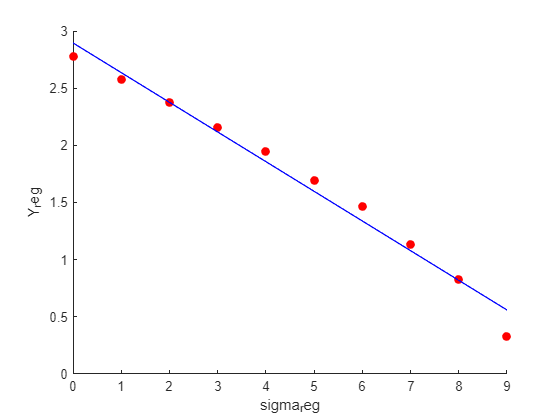


% Calcolo del decremento logaritmico 
M = length(pks);       % Numero di picchi trovati
k = (0:M-1)';          % Vettore degli indici dei picchi [0, 1, 2, ..., M-1]
z = log(abs(pks));         

sigma_reg =[-k , ones(M, 1)];

Y_reg = [z];

% tetha_LS = inv(sigma_reg' * sigma_reg) * sigma_reg'*Y_reg;
tetha_LS = sigma_reg \ Y_reg;

% Stampa retta di regressione

figure;
hold on 
plot(k, Y_reg, 'ro', 'MarkerFaceColor', 'r');
plot(k, -tetha_LS(1)*k+tetha_LS(2), 'b');
% axis([0 2 -40 40])
xlabel('sigma_reg');
ylabel('Y_reg');
hold off





% % Calcolo dello smorzamento 
xi_hat = tetha_LS(1);        % La stima del decremento logaritmico
delta_hat = xi_hat / sqrt(pi^2 + xi_hat^2);
T_k = diff(t_k);
omega_k_hat = pi ./ T_k;
omega_hat = mean(omega_k_hat);
omega_n_hat = omega_hat / sqrt(1 - delta_hat^2);
fprintf('Stima Smorzamento (delta): %.4f\n', delta_hat);

Stima Smorzamento (delta): 0.0823


fprintf('Stima Frequenza Naturale (omega_n): %.2f rad/s\n', omega_n_hat);

Stima Frequenza Naturale (omega_n): 24.98 rad/s


J_b = 1.4/1000; % Kgmq

B_b_hat = J_b*2*delta_hat*omega_n_hat;
k_hat = J_b*omega_n_hat^2;

fprintf('Beam viscous friction coefficient (B_b_hat): %.4f\n', B_b_hat);

Beam voscous friction coefficient (B_b_hat): 0.0058


fprintf('Elastic Joint stiffness (k_hat): %.2f Nm/rad\n', k_hat);

Elastic Joint stiffness (k_hat): 0.87 Nm/rad


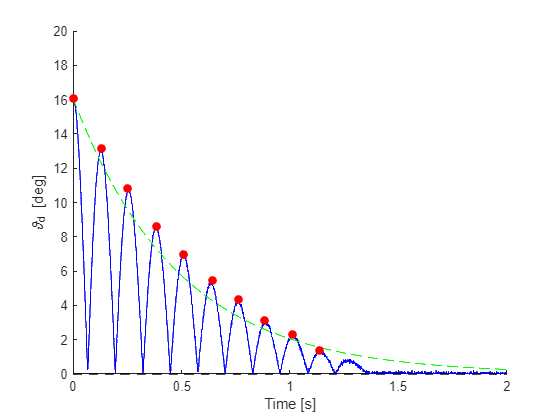


% Calcola curva
omega_A = omega_n_hat*sqrt(1-delta_hat^2);
sigma_A = -delta_hat*omega_n_hat;
A_curve = sqrt(tetha_d1(1)^2+((-sigma_A*tetha_d1(1))/omega_n_hat)^2);
z_A = A_curve *exp(sigma_A*t1);

figure;
hold on 
plot(t1,abs(tetha_d1),'b');
plot(t1,z_A,'g--');
plot(t_k, pks, 'ro', 'MarkerFaceColor', 'r');
yline(0, 'k--', 'LineWidth', 1.5);
axis([0 2 0 20])
xlabel('Time [s]');
ylabel('\vartheta_d [deg]');
hold off